# 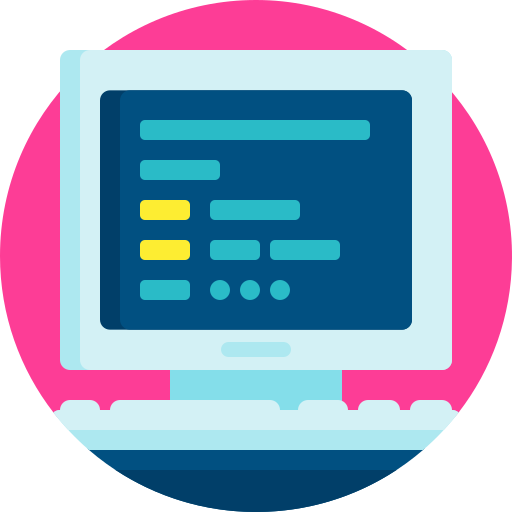

# Virtual Lab 7 - Wheeled robot kinematics

### This Virtual Lab covers Chapter 6 of the notes.

- This Virtual Lab will require both pen-on-paper work, as well as the use of MATLAB coding. The intention is to be able to solve the problems on paper (as you would in a Test/Exam) and then ratify the result using MATLAB.

- Make sure to save this file somewhere where you can access it again later, e.g. Google Drive/OneDrive/MATLAB Drive (or on your PC if you are working on a laptop). 

- This live script is intended to be used with the code shown. Select the `VIEW` tab and switch to `Output on right`.

- Each Section of this Live Script must be run individually. You can run Sections by using the `Run Section` button under the `LIVE EDITOR` ribbon (at the top of the screen), or using CNTL+ENTER (Windows) or CMD+ENTER (macOS).

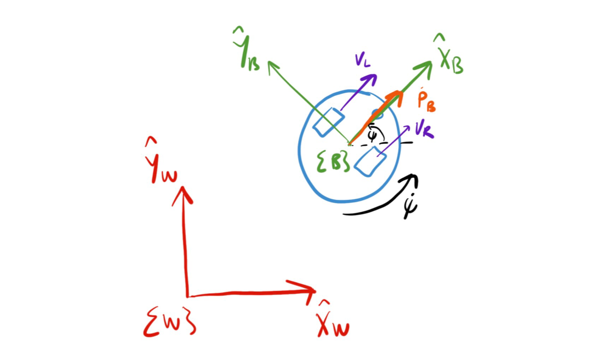

### Using the Robotics System Toolbox

This Virtual Lab will make use of the Robotics System Toolbox to get a better understanding of the kinematics of differentially-steered robots. We will start by defining our robot using the `differentialDriveKinematics `function

robot = differentialDriveKinematics( TrackWidth=0.5, WheelRadius=0.5 )

`robot` is defined to have a wheel-to-wheel distance (TrackWidth) of 0.5 m and wheel radii of 0.5 m. We will assume that the robot has an initial configuration of 

robotPose = [0 0 0]';    %3x1 pose vector

where `robotPose `is equivalent to ${^W{\bf\xi}_B}={^W[p_x~~p_y~~\psi]^T}$ — the $3\times1$pose vector, made up of the planar translation and 1D rotation angle.

Our wheeled robot is non-holonomic, so we cannot find pose directly, but we can find the rate of change of pose if we know the current wheel speeds (`phiL `and `phiR`) and current pose. We will use the `derivative `function to find the pose-rate in frame $\{W\}$

phiL = 0;   %left wheel angular velocity
phiR = 0;   %right wheel angular velocity
robotVelocity = derivative( robot,robotPose, [phiL,phiR] )    %velocity vector of robot in frame {W}

With zero velocity on both wheels, it should not be surprising that our world-frame velocity vector is equal to zero. Once we have found our velocity (`robotVelocity`), we can integrate it numerically to update the robot pose in the inertial-frame. First-order Euler integration is given by

dT = 0.1; %sample time
robotPose = robotPose + dT*robotVelocity

Again, hopefully unsurprising — we started off with a pose of ${^W{\bf\xi}_B}=[0~0~0]^T$, our wheel velocities remained at zero, and our update pose did not change. In the general case this wont be true as we start commanding angular velocities on each wheel. Note that we should ideally use the exponential mapping to perform an exact integration of the velocities, but we will use Euler integration here to simplify the details.

We can visualise our robot using the following command

figure(1),clf
plotTrVec = [robotPose(1:2); 0];    %3D position of robot
plotRot = [cos(robotPose(3)/2) 0 0 sin(robotPose(3)/2)]; %quaternion that encodes 1D orientation
plotTransforms(plotTrVec', plotRot, "MeshFilePath", "groundvehicle.stl", "Parent", gca, "View","2D", "FrameSize", robot.TrackWidth/.1);
% light;
axis([-20 20 -20 20])
grid on

We can also send the robot wheel velocity commands and see how it moves using a `for` loop in conjunction the `rateControl `function. `rateControl `effectively sets up a `MATLAB` timer that will cause the `for` loop to timeously iterate based on the specified input. This is important when we use integration, as our integration time must match how the animation updates.

dT = 0.1;
timer = rateControl(1/dT);  %set up a timer with a duration of dT seconds.

phiL = -12; %rad/s
phiR = -12; %rad/s


robotPose = [1 0 0]';
for i=1:(5/dT)  %run the simulation for a time equivalent to 5 seconds
    figure(1),clf

    robotVelocity = derivative( robot,robotPose, [phiL,phiR] );
    robotPose = robotPose + dT*robotVelocity;

    plotTrVec = [robotPose(1:2); 0];    %extract 2D position of robot
    plotRot = [cos(robotPose(3)/2) 0 0 sin(robotPose(3)/2)]; %quaternion that encodes 1D orientation
    
    axis([-20 20 -20 20])   %sets x- and y-axis limits.
    grid on
    plotTransforms(plotTrVec', plotRot, "MeshFilePath", "groundvehicle.stl", "Parent", gca, "View","2D", "FrameSize", robot.TrackWidth/.1);
    light
    drawnow
    waitfor(timer);
end


Mess around with different wheel velocity inputs and ensure that how the robot pose changes make sense. You may need to adjust the axis limits depending on how exotic the wheel velocities are.

#### **Question 1: What combination of left and right wheel velocities will result in an angular velocity of **$\dot{\psi}=10 ~\text{rad/s}$ with zero translational velocity**?**

%Add code here


#### **Question 2: What combination of left and right wheel velocities will result in an angular velocity of **$\dot{\psi}=10~\text{rad/s}$ with a translational velocity of $v=2~\text{m/s}$**?**

%Add code here


### Instantaneous centre of rotation

The instantaneous centre of rotation (ICR) is a useful 2D point that can be used to give us a better understanding of the instantaneous rate of change of translation and rotation.

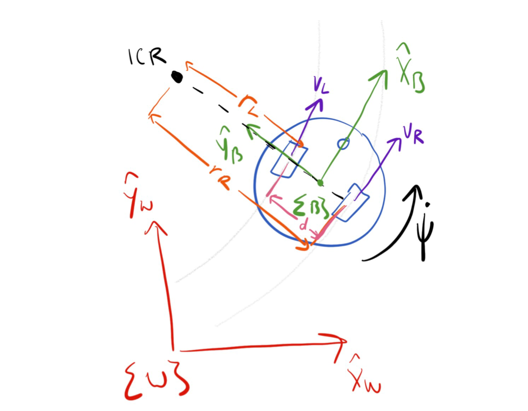

#### **Question 3: **Given an angular velocity of $\dot{\psi}=5~\text{rad/s}$ and a linear velocity of $v=1~\text{m/s}$, find body-frame location of the ICR.

%Add code here


#### **Question 4: **Using your answer from** Question 3, **and given a robot pose of $\xi=[1~ 0~ \pi/4]^T$, find the world-frame location of the ICR.

%Add code here


### Forward kinematics of a differentially-steered robot

The `robot `object and `derivative` function from the `Robotics System Toolbox` are a convenient means of constructing our forward kinematics, but we can also develop and code it from first principles (and should be able to in the Test/Exam!). Use your understanding of the forward kinematics to write code that *replaces* the following line of code in the `for` loop.

The replacement code should be written from first principles (no use of Robotics System Toolbox functions) and should generate the same motion as above. 

%Add code here


#### **Question 5: **Upload the forward kinematic code as your answer.

*Hint: You could simultaneously plot the pose of the "original" robot and your robot to ensure that the forward kinematics match.*

### Inverse kinematics of a differentially-steered robot

The previous Sections should have demonstrated that we can define a forward kinematic mapping from wheel speeds to pose-rate

${^W \dot{\bf \xi}_B = \left[\matrix{\cos\psi  & 0 \cr \sin\psi &  0\cr
0 &  1 }\right]\left[\matrix{v \cr \dot{\psi}}\right]=\left[\matrix{\frac{\cos\psi}{2}  & \frac{\cos\psi}{2} \cr \frac{\sin\psi}{2} &  \frac{\sin\psi}{2} \cr
-\frac{1}{d} &  \frac{1}{d} }\right]\left[\matrix{v_L \cr v_R }\right]$,

where $v=\frac{v_L+v_R}{2}$ and $\dot{\psi}=\frac{v_R-v_L}{d}$.

We can then numerically integrate the above result in order to obtain ${^W\bf \xi}_B$. So there is a direct relationship between wheel velocities and rate of change of pose. We can try invert this relationship in order to specify the desired pose-rate, ${^W \dot{\bf \xi}_B^{\ast}$, and then find the corresponding wheel velocities, but we need to be careful about whether we have sufficient controllable degrees of freedom. Our wheeled robot has two controllable degrees of freedom ($v_L$ and $v_R$), but the pose-rate has three degrees of freedom ($p_x$, $p_y$, and $\dot{\psi}$). For this reason, we can only hope to specify two pose-rate elements. Discarding the desired angular rate, we can *square up *the above equation as

$\left[\matrix{p_x^\ast \cr p_y^\ast}\right]=
\left[\matrix{\cos\psi  & 0 \cr \sin\psi  & 0}\right]\left[\matrix{v \cr \dot{\psi}}\right]
=\left[\matrix{\frac{\cos\psi}{2}  & \frac{\cos\psi}{2} \cr \frac{\sin\psi}{2} &  \frac{\sin\psi}{2} }\right]\left[\matrix{v_L \cr v_R }\right]$.

To keep the derivation simple, we will try solve for required linear and angular velocities of the robot: $v$ and $\dot{\psi$

$\left[\matrix{v \cr \dot{\psi}}\right]
=
{\bf A}\left[\matrix{p_x^\ast \cr p_y^\ast}\right]

=
\left[\matrix{\cos\psi  & 0 \cr \sin\psi  & 0}\right]^{-1}
\left[\matrix{p_x^\ast \cr p_y^\ast}\right]
$.

Use `MATLAB`'s [`symbolic toolbox`](https://www.mathworks.com/products/symbolic.html) to find $\bf A$ (or calculate the inverse manually).

%Add code here.


What you should find is that the inverse does not exist. Specifically, the determinant is equal to zero, which results in a singularity.

%Add code here to check determinant.


Intuitively, this is because the angular velocity and linear velocity in the world frame are completely decoupled as a result of us placing frame $\{B \}$ in the centre of the two wheels.

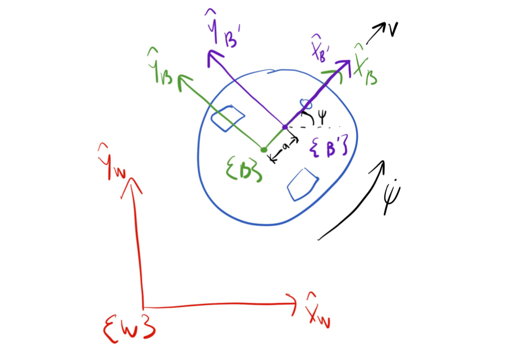

A way around this is to redefine our reference frame of interest such that angular velocities end up affecting the world-frame translational velocities. With reference to the figure above, if we offset frame $\{B\}$ by an amount of $a$ in the direction of the $\hat{\bf x}_B$-axis, we will end up with the newly defined reference frame of $\{B'\}$. Using this structure, the translational velocity of the frame $\{B'\}$ origin, with respect to frame $\{W\}$, becomes

$\left[\matrix{p_x^\ast \cr p_y^\ast}\right]=
{\bf C} \left[\matrix{v \cr \dot{\psi}}\right]
=
\left[\matrix{\cos\psi  & -a\sin\psi \cr \sin\psi  & a\cos\psi}\right]\left[\matrix{v \cr \dot{\psi}}\right]$.

Use MATLAB and the symbolic toolbox to find the inverse of ${\bf C}$.

%Add code here.


#### **Question 6: What is the transformation matrix that defines **${^B{\bf T}_{B'}}$ if $a=1 \text{m}$?

We can now derive the robot-frame velocities ($v$ and $\dot{\psi}$) using the adjusted formulation

$\left[\matrix{v \cr \dot{\psi}}\right]
=
{{\bf C}}^{-1}\left[\matrix{p_x^\ast \cr p_y^\ast}\right]

=
\left[\matrix{\cos\psi  & -a\sin\psi \cr \sin\psi  & a\cos\psi}\right]^{-1}
\left[\matrix{p_x^\ast \cr p_y^\ast}\right]
$.

Noting from before that $v=\frac{v_L+v_R}{2}$ and $\dot{\psi}=\frac{v_R-v_L}{d}$, we can represent these two equations in matrix form as

$\left[ \matrix{v \cr \dot{\psi} }\right]=\left[ \matrix{ \frac{1}{2} & \frac{1}{2} \cr \frac{-1}{d} & \frac{1}{d} }\right]
\left[ \matrix{ v_L \cr v_R}\right]
=
\left[ \matrix{ \frac{r_W}{2} & \frac{r_W}{2} \cr \frac{-r_W}{d} & \frac{r_W}{d} }\right]
\left[ \matrix{ \dot{\phi}_L \cr \dot{\phi}_R}\right]$.

So if we have determined the robot velocities required ($v$ and $\dot{\psi}$),  we can find the corresponding wheel velocities (be it linear or angular velocities).

Use the [`symbolic toolbox`](https://www.mathworks.com/products/symbolic.html) to find (algebraic) $\dot{\phi}_L$ and $\dot{\phi}_R$ as a function of $r_W$, $d$, $v$, and $\dot{\psi}$.

%Add code here


Assuming your code is all correct, we now have a means of mapping task space (world-frame) translational velocity requirements to each wheel.

Let us start with something simple to test out that our understanding is correct. Specify a velocity trajectory that commands the robot to move at a rate of $^W(\dot{p_x},\dot{p_y})=(3,3)$m/s from its initial configuration of ${^W{\bf \xi}_B=[0 ~ 0 ~ 0]^T$ and use this information to determine the required wheel speeds.  Use $a=1$m when defining the location of frame $\{B'\}$.

%Add code here.


You can confirm that the velocity is correct by adding the following code to your loop (before drawnow)

You will also need to add 

Before the loop, so that `figure(2)` is cleared before each simulation.

#### Question 7: Upload a .gif of the f`igure(2) animation`. 

Try out some different velocity commands and see how the motion evolves.

#### Question 8: What orientation corresponds with the desired world-frame velocity of $^W(\dot{p_x},\dot{p_y})=(3,3)$?

%Add code here (if need be)


What you should notice from the simulation is that the velocity of the frame $\{B\}$ origin in not initially equal to the desired amount and this is because the vehicle is initially not oriented in the correct direction. The two wheels therefore need to first adjust their relative speeds until such time that the orientation is correct. However, if we were to plot the velocity of $\{B'\}$, we would see that the translational velocity is instantaneously achieved.

#### Question 9: What is the algebraic relationship between the robot orientation and linear velocity?

%Add code here (if need be)


### Tracking a circle using the ICR

You are tasked with generating a circular path that the differentially-steered robot can follow. The circle is centred at $(0,5)$in the world frame and has a diameter of $10$. Using the same starting configuration of ${^W{\bf \xi}_B=[0 ~ 0 ~ 0]^T$, answer the following questions.

Use the concept of the instantaneous centre of rotation to produce velocity commands for the wheeled robot in order to follow the aforementioned circular path. The robot must complete the full circle at $t=5$ seconds (when the `for` loop ends). Use a sample time of `dT=0.05` seconds or lower.

%Add code here


#### Question 10: Upload a .gif of your simulation. The plot must show the circular path as well as the robot as it traverses the path.

If you are bored, see if you can find a way to generate the circular trajectory using inverse kinematics!

%Add code here


#### Question 11: Upload your completed Virtual Lab .mlx file in Amathuba. Make sure to include your student number in the file name.